% cart / pole Fuzzy inference System

cpFIS = newfis('Cartfuzz');

cpFIS = addvar(cpFIS,'input','Theta',[-pi pi])

cpFIS = struct with fields:
            name: 'Cartfuzz'
            type: 'mamdani'
       andMethod: 'min'
        orMethod: 'max'
    defuzzMethod: 'centroid'
       impMethod: 'min'
       aggMethod: 'max'
           input: [1×1 struct]
          output: []
            rule: []


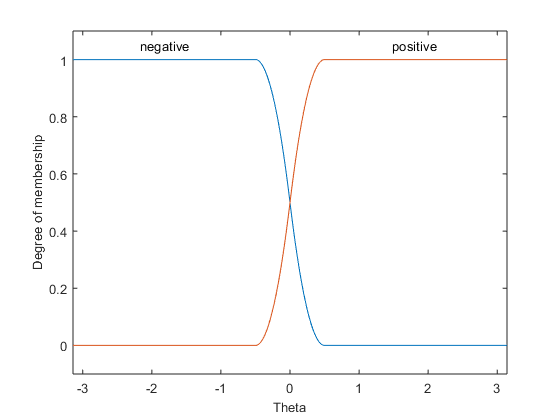

cpFIS = addmf(cpFIS,'input',1,'negative','zmf',[-0.5 0.5]);
cpFIS = addmf(cpFIS,'input',1,'positive','smf',[-0.5 0.5]);


plotmf(cpFIS, 'input', 1, 1000)